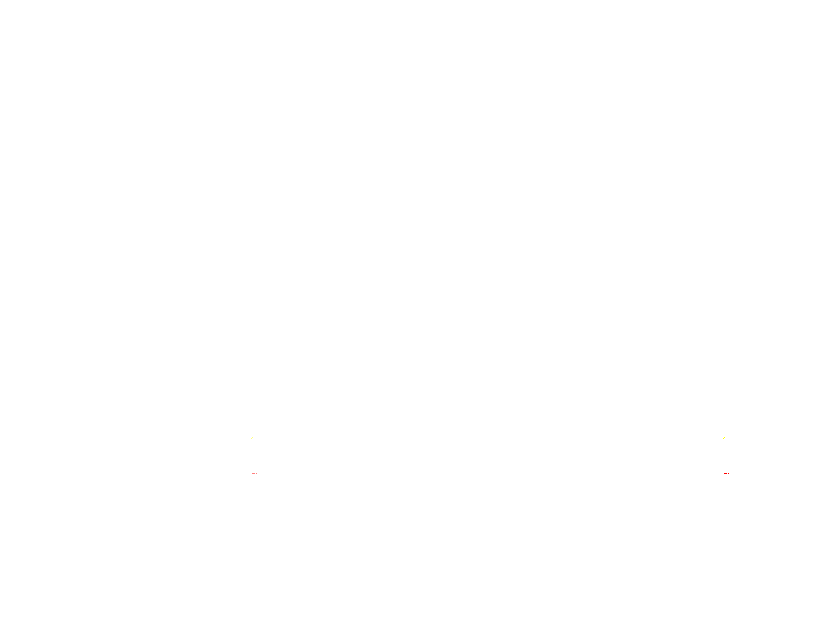

load('ignitionCropped.mat');

videoFrames = double(videoFrames);

figure
for t = 1:size(videoFrames,4)
    subplot(1,3,3);
    imshow(videoFrames(:,:,:,t));
    
    colourArrayOriginal = data2rgbV2(videoFrames(:,:,:,t));
    subplot(1,3,1);
    imshow(colourArrayOriginal(:,:,:));
end


dmd = DynamicModeDecomposer(videoFrames,"rank",10);

ans =       249912          54


snapshotMatrix = 	1.0e+02 *

   1.0473 - 0.0000i   1.0095 - 0.0000i   0.9730 - 0.0000i   0.9409 - 0.0000i   0.9150 - 0.0000i   0.8948 - 0.0000i   0.8789 - 0.0000i   0.8654 - 0.0000i   0.8534 - 0.0000i   0.8427 - 0.0000i   0.8343 - 0.0000i   0.8288 - 0.0000i   0.8265 - 0.0000i   0.8270 - 0.0000i   0.8289 - 0.0000i   0.8307 - 0.0000i   0.8313 - 0.0000i   0.8301 - 0.0000i   0.8273 - 0.0000i   0.8234 - 0.0000i   0.8192 - 0.0000i   0.8153 - 0.0000i   0.8120 - 0.0000i   0.8091 - 0.0000i   0.8063 - 0.0000i   0.8037 - 0.0000i   0.8009 - 0.0000i   0.7983 - 0.0000i   0.7961 - 0.0000i   0.7943 - 0.0000i   0.7932 - 0.0000i   0.7925 - 0.0000i   0.7921 - 0.0000i   0.7916 - 0.0000i   0.7908 - 0.0000i   0.7895 - 0.0000i   0.7878 - 0.0000i   0.7857 - 0.0000i   0.7831 - 0.0000i   0.7802 - 0.0000i   0.7769 - 0.0000i   0.7732 - 0.0000i   0.7691 - 0.0000i   0.7647 - 0.0000i   0.7599 - 0.0000i   0.7549 - 0.0000i   0.7497 - 0.0000i   0.7446 - 0.0000i   0.7395 - 0.0000i   0.7346 - 0.0000i
   1.0473 - 0.0000i 

ans =       249912          54


meanMatrix =    35.9600   26.3590   30.7335   -0.2150   -5.9246  -24.6855  -11.1856   -8.4909   -2.1052  -28.9244  -21.5073  -50.6616  -24.8272  -44.4540  -38.4167  -59.7100  -58.1912  -75.7110  -62.5743  -76.8476  -71.2356  -83.0545  -71.7335  -78.9139  -68.8585  -69.8207  -44.5731  -44.2000  -32.6324  -33.9650  -17.2601  -18.5912   -5.0032   -2.6341   13.0540   13.4749   24.4307   19.9105   32.1846   26.1761   32.5413   25.9088   30.2087   20.3735   25.8331   19.1440   27.0030   27.5502   33.0515   25.0302
   35.9600   26.3590   30.7335   -0.2150   -5.9246  -24.6855  -11.1856   -8.4909   -2.1052  -28.9244  -21.5073  -50.6616  -24.8272  -44.4540  -38.4167  -59.7100  -58.1912  -75.7110  -62.5743  -76.8476  -71.2356  -83.0545  -71.7335  -78.9139  -68.8585  -69.8207  -44.5731  -44.2000  -32.6324  -33.9650  -17.2601  -18.5912   -5.0032   -2.6341   13.0540   13.4749   24.4307   19.9105   32.1846   26.1761   32.5413   25.9088   30.2087   20.3735   25.8331   19.1440   27.0030   27.5502   33.


%figure

% for t = 1:size(dmd.reconstructedDataMatrix,4)
%     subplot(1,3,3);
%     imshow(videoFrames(:,:,:,t));
%     
%     colourArrayOriginal = data2rgbV2(dmd.reconstructedDataMatrix(:,:,:,t));
%     subplot(1,3,1);
%     imshow(colourArrayOriginal(:,:,:));
% end


function colourArray = data2rgb(data)
    colourArray = real(data(:,:,:));
    maxVal = max(colourArray(:,:,:));
    minVal = min(colourArray(:,:,:));
    colourArray = uint8(255*double(double(colourArray(:,:,:) - minVal) ./ double( maxVal - minVal)));
end

function colourArray = data2rgbV2(data)
    colourArray = real(data(:,:,:));
    
    if isa(colourArray,'double')
        colourArray = (data(:,:,:) + 1) ./ 2;
        colourArray = uint8(colourArray*255);
    else
        return;
    end
end
